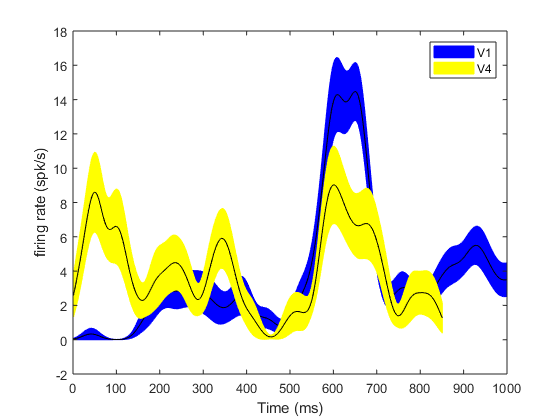

I=2; %Inhibitory Visual Neuron
% V1
newV1sp=[VSpike(:,1:1050); VASpike(:,1:1050); VMSpike(:,1:1050)];
[V1Tlen,~]=size(newV1sp);
sd=20;
V1fr = 1000*smooth(newV1sp, sd);
V1mfr= mean(V1fr,1);
V1sdfr=std(V1fr,[],1);
V1sefr=V1sdfr/sqrt(V1Tlen);
t=[1:length(newV1sp)];

e1=V1mfr-V1sefr;
e2=V1mfr+V1sefr;
figure
% h1=subplot(2,1,1);
L(1)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'b','EdgeColor','b','FaceColor','b');
hold on;
plot(t,V1mfr,'Color','k','LineStyle','-')
% V4
newV4sp=[VSpike(:,t2-450:end)];
[V4Tlen,~]=size(newV4sp);
sd=20;
V4fr = 1000*smooth(newV4sp, sd);
V4mfr= mean(V4fr,1);
V4sdfr=std(V4fr,[],1);
V4sefr=V4sdfr/sqrt(V4Tlen);
t=[1:length(newV4sp)];

e1=V4mfr-V4sefr;
e2=V4mfr+V4sefr;
% 
L(2)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'y','EdgeColor','y','FaceColor','y');
hold on;
plot(t,V4mfr,'Color','k','LineStyle','-')
xlabel('Time (ms)')
ylabel('firing rate (spk/s)')
xlim([0 1000])
legend(L,{'V1','V4'});

% 
Q1=1;
Q2=851;
var1=V1sdfr(Q1:Q2).^2;
var2=V4sdfr(Q1:Q2).^2;
var3=V1sefr(Q1:Q2).^2;
var4=V4sefr(Q1:Q2).^2;
rdif=V1mfr(Q1:Q2)-V4mfr(Q1:Q2);
Nr=length(rdif);
SEdif=sqrt(var3+var4);
e1=rdif-SEdif;
e2=rdif+SEdif;
t=[Q1:Q2];
% h2=subplot(2,1,2);
% fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'g','EdgeColor','g','FaceColor','g')
% hold on 
% plot(t,rdif,'Color','k','LineStyle','-')
% xlabel('Time (ms)')
% ylabel('firing rate (spk/s)')
% xlim([0 1000])
%Determine significant difference
[VWMItse,VWMPtse] = detsign(rdif,SEdif,Q1,Q2,1);

No Visual Within Modal Potentiation


Vrdif=rdif;
VSEdif=2*SEdif;

o=1; p=2;
q=1; 
if I==1
    VWMItse1=VWMItse(o);
    VWMItse2=VWMItse(p);
    VWMPtse1=VWMPtse(q);
    VWMPtse2=VWMPtse(q);
else
    VWMItse1=VWMItse(q);
    VWMItse2=VWMItse(q);
    VWMPtse1=VWMPtse(o);
    VWMPtse2=VWMPtse(p);
end

Index exceeds the number of array elements (1).



% axes(h1)
title({'';'Firing Pattern for V1 vs V4'})
if I==1
    line([VWMItse1 VWMItse1],ylim,'Color','r','HandleVisibility','off');
    line([VWMItse2 VWMItse2],ylim,'Color','r','HandleVisibility','off');
else
    line([VWMPtse1 VWMPtse1],ylim,'Color','r','HandleVisibility','off');
    line([VWMPtse2 VWMPtse2],ylim,'Color','r','HandleVisibility','off');   
end

% axes(h2)
% title({'';'Difference between V1 and V4'})
% if I==1
%     line([VWMItse1 VWMItse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMItse2 VWMItse2],ylim,'Color','r','HandleVisibility','off');
% else
%     line([VWMPtse1 VWMPtse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMPtse2 VWMPtse2],ylim,'Color','r','HandleVisibility','off');   
% end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % A1
% newA1sp=[ASpike(:,1:1050); AVSpike(:,1:1050); AMSpike(:,1:1050)];
% [A1Tlen,~]=size(newA1sp);
% sd=20;
% A1fr = 1000*smooth(newA1sp, sd);
% A1mfr= mean(A1fr,1);
% A1sdfr=std(A1fr,[],1);
% A1sefr=A1sdfr/sqrt(A1Tlen);
% t=[1:length(newA1sp)];
% 
% e1=A1mfr-A1sefr;
% e2=A1mfr+A1sefr;
% figure
% h1=subplot(2,1,1);
% L(1)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'r','EdgeColor','r','FaceColor','r');
% hold on;
% plot(t,A1mfr,'Color','k','LineStyle','-')
% 
% % VA4
% newVA4sp=[VASpike(:,t2-450:end)];
% [VA4Tlen,~]=size(newVA4sp);
% VA4fr = 1000*smooth(newVA4sp, sd);
% VA4mfr= mean(VA4fr,1);
% VA4sdfr=std(VA4fr,[],1);
% VA4sefr=VA4sdfr/sqrt(VA4Tlen);
% t=[1:length(newVA4sp)];
% e1=VA4mfr-VA4sefr;
% e2=VA4mfr+VA4sefr;
% L(2)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'y','EdgeColor','y','FaceColor','y');
% plot(t,VA4mfr,'Color','k','LineStyle','-')
% xlim([0 1000])
% xlabel('Time (ms)')
% ylabel('firing rate (spk/s)')
% legend(L,{'A1','VA4'});
% % 
% Q1=1;
% Q2=851;
% var1=A1sdfr(Q1:Q2).^2;
% var2=VA4sdfr(Q1:Q2).^2;
% var3=A1sefr(Q1:Q2).^2;
% var4=VA4sefr(Q1:Q2).^2;
% rdif=A1mfr(Q1:Q2)-VA4mfr(Q1:Q2);
% Nr=length(rdif);
% SEdif=sqrt(var3+var4);
% e1=rdif-SEdif;
% e2=rdif+SEdif;
% t=[Q1:Q2];
% h2=subplot(2,1,2);
% fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'g','EdgeColor','g','FaceColor','g')
% hold on 
% plot(t,rdif,'Color','k','LineStyle','-')
% xlabel('Time (ms)')
% ylabel('firing rate (spk/s)')
% xlim([0 1000])
% %Determine time points of significant difference
% [VIAtse,VPAtse] = detsign(rdif,SEdif,Q1,Q2,2);
% 
% 
% axes(h1)
% title({'';'Firing Pattern for A1 vs VA4'})
% if I==1
%     line([VWMItse1 VWMItse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMItse2 VWMItse2],ylim,'Color','r','HandleVisibility','off');
% else
%     line([VWMPtse1 VWMPtse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMPtse2 VWMPtse2],ylim,'Color','r','HandleVisibility','off');   
% end
% axes(h2)
% title({'';'Difference between A1 and VA4'})
% if I==1
%     line([VWMItse1 VWMItse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMItse2 VWMItse2],ylim,'Color','r','HandleVisibility','off');
% else
%     line([VWMPtse1 VWMPtse1],ylim,'Color','r','HandleVisibility','off');
%     line([VWMPtse2 VWMPtse2],ylim,'Color','r','HandleVisibility','off');   
% end